# Linearized Kalman Filter

This program just does 1 run of an LKF.

% bringing in simulation data and provided data
load sim_setup.mat
load orbitdetermination-finalproj_data_2023_11_14.mat
% Bringing in required functions and variables 
addpath('./functions/')

## Simulation Settings and Useful Constants

m = length(a_SRP);                      % number of inputs equals the length of this vector
p = 2;                                  % number of measurement variables per landmark
x_0 = [r_nom; dr_nom];                  % initial state
n = length(x_0);                        % number of state variables
dt = dt_int;                            % chosen step size
% dt = dt_obs; 
t_obs = unique(y_table(:, 1));          % times of observations [s]
t = -dt:dt:max(t_obs);                  % time vector for LKF
steps = length(t);                      % number of time steps in used in LKF
steps_obs = length(t_obs);

% --- number of landmarks to use --- 
num_marks = length(pos_lmks_A);
lps = pos_lmks_A(:,1:num_marks);

## System Matrices and Noise

These are static

% --- Static system matrices ---
% CT B matrix
B = zeros(n,m);
B(4:end,:) = eye(3);

% Static input
u = a_SRP;

% CT Gamma matrix 
Gamma = zeros(n,m);
Gamma(4:end,:) = eye(3);

% CT Noise matrices
W_truth = eye(m)*sig_w^2;
W = eye(m)*sig_w^2*1e5;
V = eye(p)*sig_v^2;
R = V/dt;   

## Inital Uncertainties and Pertibations

% -- initial uncertainty and pertibations --- 
pos_uncert = ones(1,3)*1e-4;                    % position 2-sigma uncertainty on order of meters
vel_uncert = ones(1,3)*1e-6;                    % velocity '                           ' of mm/s
P_0 = diag([pos_uncert.^2/4,vel_uncert.^2/4]);  % Initial uncertainty matrix
x_pert = mvnrnd(zeros(n,1),P_0)';               % Random initial uncertainty gerated from uncertainty matrix

## State Truth Models

### Ode45 Truth States Generation: No Noise

Simply Solving the ode for all of time with the given "truth" initial conditions.

% pure ODE solution with no noise
options = odeset('RelTol',1e-12);               % ODE45 options
[~,x_ode_clean] = ode45(@(t_in,x_in) orbit(t_in,x_in,a_SRP,mu_A), t, x_0', options);

% adding noise via DT LTI model
dx_DT = zeros(steps,n); 
dx_DT(1,:)= x_pert';
x_DT = zeros(steps,n);
x_DT(1,:) = x_0';
for k = 1:steps-1
    % calculating nominal state
    x_nom_k = x_ode_clean(k,:)';
    
    % Jacobians for nominal state
    A = dfdx(x_nom_k,mu_A);

    % Putting this in the discrete time 
    [F,G,Q] = state_CT_to_DT(dt,A,B,Gamma,W_truth);
    w_k = mvnrnd(zeros(n,1),Q)';

    % deviation at the next time step
    dx_k_plus = F*dx_DT(k,:)'+ G*u + w_k;

    % saving these 
    dx_DT(k+1,:) = dx_k_plus';
    x_DT(k+1,:) = x_nom_k' + dx_k_plus';
end

## Measurement Truth Model

Choosing a state truth model

x_truth = x_DT;                                 % Choosing truth state model
y_truth = zeros(p*num_marks,steps_obs);         % 3D array of measurments at each OBSERVATION step. 
                                                %  -->  NOTE: indexing order
                                                %       is strange to not
                                                %       have to flatten
                                                %       results
% retrieving measurments for each measurement step
for meas_idx = 1:steps_obs                      
    t_obs_meas = t_obs(meas_idx);               % Time of measurement
    [~,k] = min(abs(t - t_obs_meas))            % index of time for model used
    x_nom_k = x_truth(k,:)';                    % Truth state at this time

    % Making truth observations at observation times
    RNC = R_CtoN(:,:,meas_idx);                 % instrument coordinate system at this time
    
    % checking measurments for every landmark at this time
    for ii = 1:num_marks 
        rows = (p*(ii-1)+1):(p*ii);             % Rows corresponding to this landmark in the measurement matrix
        lp = lps(:,ii);                         % landmark location 
        % making the noisy measurement at this time, this satellite
        % location, for this landmark.
        y_truth(rows,meas_idx) = y_measured(lp,x_nom_k,RNC,t(k),true,true);
    end
end

## Linearized Kalman Filter

% --- Initializing vectors for LKF --- 
% creating useful vectors for all times 
dx_plus = zeros(steps,n);                               % state correction after measurment
X_plus = zeros(steps,n);                                % total state after measurement
P_plus = zeros(n,n,steps);                              % residuals after measurement
eps_X = zeros(steps,1);                                 % NEES
eps_y = zeros(steps,1);                                 % NIS

% initializing these vectors 
dx_plus(1,:) = x_pert';
X_plus(1,:) =  x_truth(1,:); 
P_plus(:,:,1) = P_0;
eps_X(1) = dx_plus(1,:) * inv(P_plus(:,:,1)) * dx_plus(1,:)';
% could initialize eps_Y, but I'm not going to for now.

% --- Performing LKF ---
% in this for loop, the current time step is k
% and the next time step is time k+1
for k = 1:steps-1
    % --- Nominal State calculation --- 
    % Using the equation solver
    % if k ~= 1
    %     % solving the ODE from last time step to this one 
    %     [t_ode,x_ode45] = ode45(@(t_in,x_in) orbit(t_in,x_in,a_SRP,mu_A), [t(k-1), t(k+1)], X_plus(k-1,:), options);
    %     [~,k_idx] = min(abs(t_ode-t(k)));             % index of current time
    %     x_nom_k = x_ode45(k_idx,:)';                        
    %     [~,k_plus_idx] = min(abs(t_ode-t(k+1)));      % index of next time
    %     x_nom_k_plus = x_ode45(k_plus_idx,:)';                     
    % else
    %     [t_ode,x_ode45] = ode45(@(t_in,x_in) orbit(t_in,x_in,a_SRP,mu_A), [t(k), t(k+1)], X_plus(k,:), options);
    %     x_nom_k = X_plus(k,:);                        % to start off, no ODE needs to be solved; just take the initial state.
    %     x_nom_k_plus = x_ode45(end,:)';               % The last element in the array is the solution for time t(k)
    % end
    
    % using the noiseless truth value
    x_nom_k = x_ode_clean(k,:)';
    x_nom_k_plus = x_ode_clean(k+1,:)';

    % --- processes for CURRENT time k ---
    t_k = t(k);                                         % time for this time step
    A = dfdx(x_nom_k,mu_A);                             % Jacobians for nominal state
    [F,G,Q] = state_CT_to_DT(dt,A,B,Gamma,W);           % Putting this in the discrete time 

    % Kalman filter prediction step
    dx_minus = F*dx_plus(k,:)' + G*u;
    P_minus = F*P_plus(:,:,k)*F' + Q;

    % If no measurment is available at next time step, make no measurment updates
    t_k_plus = t(k+1);
    if mod(t_k_plus,dt_obs) ~= 0                        
        dx_plus(k+1,:) = dx_minus';                     % Next state pertibation is uncorrected predicted pertibation
        P_plus(:,:,k+1) = P_minus;                      % residuals for next state is the uncorrected residuals
        X_plus(k+1,:) = x_nom_k_plus' +  dx_minus';     % Next total state is the nominal plus the uncorrected at that state
        continue                                        % Do not make corrections; skip rest of loop
    end

    % --- processes for NEXT time step k, after measurement taken --- 
    % time, nominal state, and RNC matrix for next time step
    meas_idx = t_k_plus / dt_obs + 1;
    RNC = R_CtoN(:, :, meas_idx);                       % ADCS instrument axes at this step
    
    % Getting valid measurements and landmarks for this time step
    y_meas = y_truth(:,meas_idx);                       % Getting measurements at this time 
    vis_rows = find(~isnan(y_meas));                    % finding all the non-NaN rows, corresponding to visible landmarks
    vis_landmarks = vis_rows(2:p:end)/p;                % index of visible landmarks is relatex to the index of non-NaN rows
    num_vis = length(vis_landmarks);                    % number of visible landmarks (Each landmark has p measurements)
    y_meas = y_meas(vis_rows);                          % Filtering for only the visible landmarks
    
    % initializing nominal measurments, H matrix, and uncertainty matrix
    y_nom = zeros(size(y_meas));                        % initialize nominal measurements
    H = ones(p*num_vis,n);                              % Initialize H matrix
    R_k = kron(eye(num_vis),R);                         % measurement noise matrix. All landmarks have same noise, so diagonal matrix

    % perfoming H matrix calculations and simulated measurements for next time step
    for i = 1:num_vis
        % Getting the visible landmark of interest
        landmark_i = vis_landmarks(i);
        lp = lps(:,landmark_i);                         % landmark coordinates in asteroid-fixed frame

        % getting expected position of landmark at next time step, with no process nosie
        y_nom_i = y_measured(lp, x_nom_k_plus, RNC, t_k_plus,false,false); 

        % obtaining H matrix for this landmark at next time step
        H_i = H_k(lp,x_nom_k_plus,t_k_plus,RNC);
        
        % storing these values 
        rows = (p*(i-1)+1):(p*i);                       % Rows corresponding to this landmark
        y_nom(rows) = y_nom_i;                          % observation difference matrix
        H(rows,:) = H_i;                                % H matrix
    end
    dy_vis = y_meas - y_nom;                            % error in measurement and expected value
    
    % Kalman filter correction step
    S = H * P_minus * H' + R_k;                         % Innovation matrix
    K = P_minus * H' * inv(S);                          % Gain matrix
    e_y_k = dy_vis - H*dx_minus;                        % Measurement error
    dx_plus(k+1,:) = (dx_minus + K*(e_y_k))';           % correction for next time step
    P_plus(:,:,k+1) = (eye(n) - K*H)*P_minus;           % Uncertainties for next time step
    X_plus(k+1,:) = x_nom_k_plus' + dx_plus(k,:);       % Total estimate state for next step  

    % --- Error calculations ---
    % state error and NEES
    e_X_k = dx_plus(k+1,:)';
    eps_X(k+1) = e_X_k' * inv(P_plus(:,:,k+1)) * e_X_k;
    
    % measurement error and NIS 
    eps_y(k+1) = e_y_k' * inv(S) * e_y_k;
end

## Plotting 

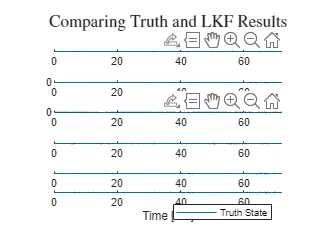

figure;
fig = tiledlayout(n,1);
ylabels =   ["$ x$ [km]", "$ y$ [km]","$z$ [km/s]", ...
            "$\dot x$ [km/s]", "$\dot y$ [km/s]","$\dot z$ [km/s]"];
for i = 1:n
    nexttile(fig)
    hold on
    plot(t/60/60,x_truth(:,i)-X_plus(:,i))
    % plot(t/60/60,X_plus(:,i))
    hold off
    xlim([t_obs(1)/60/60, 72])
    ylabel(ylabels(i),Interpreter='latex')
end
xlabel("Time [hrs]")
title(fig,"Comparing Truth and LKF Results", Interpreter='latex')